# Identyfikacja modelu dynamiki poprzecznej pojazdu

**Modelowanie i Identyfikacja**

Politechnika Gdanska, Wydzial Elektrotechniki i Automatyki

Kierunek: Automatyka, Robotyka i Systemy Sterowania, II stopien

Cwiczenie laboratoryjne: metody czarnej i szarej skrzynki

Aby otworzyc ten plik jako Live Script: kliknij prawym przyciskiem na zakladke pliku w edytorze MATLAB i wybierz "Open as Live Script".

## Generacja danych -- model rowerowy dynamiki poprzecznej

Parametry fizyczne pojazdu 

m  = 1500; % masa [kg]
Iz = 2500; % masowy moment bezwladnosci wzgledem osi pionowej [kg*m^2]
a  = 1.2; % odleglosc osi przedniej od srodka masy [m]
b  = 1.6; % odleglosc osi tylnej od srodka masy [m]
Cf = 55000; % wspolczynnik odpornosci na znoszenie opon przednich [N/rad]
Cr = 60000; % wspolczynnik odpornosci na znoszenie opon tylnych [N/rad]
Vx = 20; % predkosc wzdluzna [m/s]

Macierze przestrzeni stanow: x = [v_y; r], u = delta, y = r

A = [-(Cf+Cr)/(m*Vx), ((b*Cr - a*Cf)/(m*Vx) - Vx);
     -(a*Cf - b*Cr)/(Iz*Vx), -(a^2*Cf + b^2*Cr)/(Iz*Vx)];
B = [Cf/m;
     a*Cf/Iz];
C = [0, 1];  % wyjscie: predkosc katowa odchylenia r
D = 0;

sys_ref = ss(A, B, C, D);

Sygnal wejsciowy: wielostopniowy skok kata skretu

Ts = 0.01; % Okres probkowania [s]
t = (0:Ts:10)'; % wektor czasu
N = length(t);
delta = zeros(N, 1);
delta(t >= 0.5 & t < 2.0) =  0.02; % [rad]
delta(t >= 3.0 & t < 4.5) = -0.03;
delta(t >= 5.5 & t < 7.0) =  0.015;
delta(t >= 8.0 & t < 9.5) = -0.025;

Symulacja i dodanie szumu pomiarowego

y_clean = lsim(sys_ref, delta, t);
rng(42);
sigma = 0.002; % odchylenie standardowe szumu [rad/s]
y_noisy = y_clean + sigma * randn(N, 1);

Utworzenie obiektu iddata

data = iddata(y_noisy, delta, Ts);
data.InputName  = {'Kat skretu kol [rad]'};
data.OutputName = {'Predkosc katowa odchylenia [rad/s]'};

Wykres sygnalu wejsciowego i wyjsciowego

figure;
subplot(2,1,1);
plot(t, delta, 'b', 'LineWidth', 1.2);
ylabel('\delta [rad]');
title('Sygnal wejsciowy i wyjsciowy');
grid on;
subplot(2,1,2);
plot(t, y_noisy, 'r', t, y_clean, 'k--', 'LineWidth', 1);
ylabel('r [rad/s]');
xlabel('Czas [s]');
legend('Pomiar (z szumem)', 'Wartosc referencyjna');
grid on;

## Zadanie 1: Eksploracja i przygotowanie danych

Rozmiar obiektu danych:

size(data)

Data set with 1 output(s) and 1 input(s).
The number of data points is 1001.


Usuniecie skladowej stalej (detrend):

data_d = detrend(data);

Podzial na zbior estymacyjny (70%) i walidacyjny (30%):

Ne = floor(0.7 * N);
data_est = data_d(1:Ne);
data_val = data_d(Ne+1:end);

fprintf('Zbior estymacyjny: %d probek\n', length(data_est.y));

Zbior estymacyjny: 700 probek


Nieparametryczna estymacja widma.

fprintf('Zbior walidacyjny: %d probek\n', length(data_val.y));

Zbior walidacyjny: 301 probek


G_spa = spa(data_est);

figure;
bode(G_spa);
title('Nieparametryczna estymacja widma (spa)');

## Zadanie 2: Identyfikacja modeli czarnej skrzynki

**Krok 1.**. Estymacja transmitancji operatorowej (tfest)

sys_tf21 = tfest(data_est, 2, 1);
sys_tf31 = tfest(data_est, 3, 1);

**Krok 2.**. Estymacja modeli ARX

sys_arx1 = arx(data_est, [2 2 1]);
sys_arx2 = arx(data_est, [3 2 1]);
sys_arx3 = arx(data_est, [4 3 1]);

**Krok 3.** Porownanie modeli na zbiorze walidacyjnym

figure;
compare(data_val, sys_tf21, sys_tf31, sys_arx1, sys_arx2, sys_arx3);
title('Porownanie modeli czarnej skrzynki na zbiorze walidacyjnym');

**Krok 4.** Porownanie charakterystyk Bodego modeli z estymatorem spa

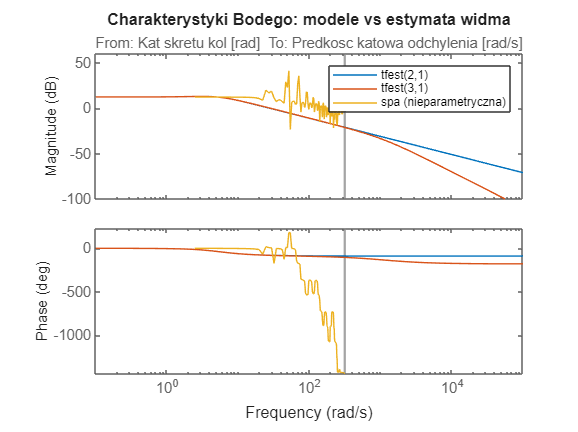

figure;
bode(sys_tf21, sys_tf31, G_spa);
legend('tfest(2,1)', 'tfest(3,1)', 'spa (nieparametryczna)');
title('Charakterystyki Bodego: modele vs estymata widma');

**Krok 5.** Analiza residuow dla najlepszego modelu

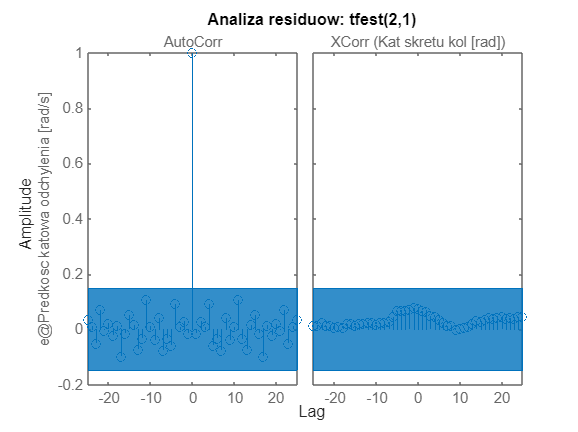

figure;
resid(data_val, sys_tf21);
title('Analiza residuow: tfest(2,1)');

**Krok 6.** Model w przestrzeni stanow (ssest)

% Estymowac model w przestrzeni stanow rzedu 2:
% sys_ss2 = ssest(data_est, ???);
% Dodac do porownania na zbiorze walidacyjnym:
% compare(data_val, sys_tf21, sys_ss2);

## Zadanie 3: Identyfikacja modelu szarej skrzynki (grey-box)

Model szarej skrzynki wykorzystuje znana strukture rownan fizycznych. Estymujemy jedynie nieznane parametry: wspolczynniki odpornosci na znoszenie Cf i Cr.

**Krok 1.** Definicja obiektu idgrey.

Cf0_k = 45; % % 45 kN/rad = 45000 N/rad
Cr0_k = 50;  % 50 kN/rad = 50000 N/rad

par0 = [Cf0_k; Cr0_k]; % wektor estymowanych parametrow
aux  = [m, Iz, a, b, Vx]; % stale parametry jako dane pomocnicze

sys_grey = idgrey('bicycle_matrices', par0, 'c', aux);

**Krok 2.** Estymacja parametrow funkcja greyest.

opt = greyestOptions('SearchMethod', 'lsqnonlin', 'Display', 'on');
sys_grey_est = greyest(data_est, sys_grey, opt);

Porownanie estymowanych parametrow z wartosciami referencyjnymi.

par_est = getpvec(sys_grey_est);
Cf_est  = par_est(1) * 1000;
Cr_est  = par_est(2) * 1000;

fprintf('Cf: referencyjne = %8.1f,  estymowane = %8.1f,  blad = %5.2f%%\n', ...
55000, Cf_est, abs(Cf_est-55000)/55000*100);

Cf: referencyjne =  55000.0,  estymowane =  56561.8,  blad =  2.84%


fprintf('Cr: referencyjne = %8.1f,  estymowane = %8.1f,  blad = %5.2f%%\n', ...
    60000, Cr_est, abs(Cr_est-60000)/60000*100);

Cr: referencyjne =  60000.0,  estymowane =  62504.8,  blad =  4.17%


Porownanie modelu szarej i czarnej skrzynki na zbiorze walidacyjnym:

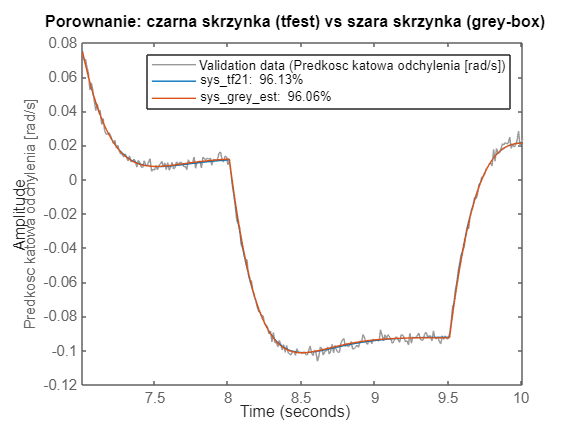

figure;
compare(data_val, sys_tf21, sys_grey_est);
title('Porownanie: czarna skrzynka (tfest) vs szara skrzynka (grey-box)');

**Krok 3.** Wrazliwosc na wartosci poczatkowe.

% Zmienic punkt startowy na Cf0_k = 30 i Cr0_k = 70,
% powtorzyc estymacje i porownac wyniki.
% Czy algorytm zbiega do tych samych wartosci?

## Zadanie 4: Test generalizacji -- zmiana predkosci wzdluznej

**Krok 1.** Generujemy nowe dane dla Vx = 30 m/s.

Vx_test = 30; % [m/s]

A_test = [-(Cf+Cr)/(m*Vx_test), ((b*Cr - a*Cf)/(m*Vx_test) - Vx_test);
          -(a*Cf - b*Cr)/(Iz*Vx_test), -(a^2*Cf + b^2*Cr)/(Iz*Vx_test)];
B_test = [Cf/m;
          a*Cf/Iz];
sys_test = ss(A_test, B_test, C, D);

y_test_clean = lsim(sys_test, delta, t);
rng(43);
y_test_noisy = y_test_clean + sigma * randn(N, 1);

data_test = iddata(y_test_noisy, delta, Ts);
data_test.InputName  = data.InputName;
data_test.OutputName = data.OutputName;
data_test = detrend(data_test);

**Krok 2.** Utworzenie modelu szarej skrzynki z estymowanymi parametrami Cf, Cr i zaktualizowana predkoscia Vx_test.

par_est_vec = getpvec(sys_grey_est); % [Cf_est; Cr_est]
aux_test = [m, Iz, a, b, Vx_test]; % zaktualizowany Vx

sys_grey_test = idgrey('bicycle_matrices', par_est_vec, 'c', aux_test);

Porownanie odpowiedzi modeli na nowych danych:

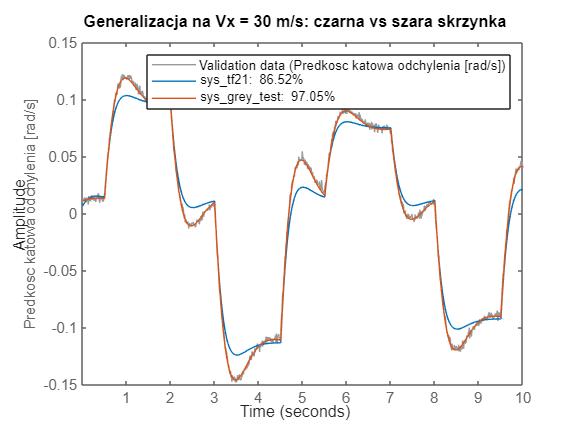

figure;
compare(data_test, sys_tf21, sys_grey_test);
title('Generalizacja na Vx = 30 m/s: czarna vs szara skrzynka');

**Krok 3.** Test generalizacji dla innych predkosci

% Powtorzyc test dla Vx_test = 15 m/s i Vx_test = 40 m/s.

## Zadanie 5: Wplyw poziomu szumu na jakosc estymacji

Powtarzamy identyfikacje grey-box dla roznych poziomow szumu, aby zbadac wariancje estymacji parametrow.

sigma_list = [0.001, 0.002, 0.005, 0.01];
results = zeros(length(sigma_list), 2);  % [Cf_est, Cr_est]

for i = 1:length(sigma_list)
    rng(42);
    y_i = y_clean + sigma_list(i) * randn(N, 1);
    data_i = iddata(y_i, delta, Ts);
    data_i = detrend(data_i);
    data_est_i = data_i(1:Ne);

    % idgrey z tymi samymi wartosciami poczatkowymi i stalymi parametrami
    sys_g = idgrey('bicycle_matrices', par0, 'c', aux);

    opt_i = greyestOptions('SearchMethod', 'lsqnonlin', 'Display', 'off');
    sys_g_est = greyest(data_est_i, sys_g, opt_i);

    par_i = getpvec(sys_g_est);
    results(i, 1) = par_i(1) * 1000; % % Cf w [N/rad]
    results(i, 2) = par_i(2) * 1000; % Cr w [N/rad]
end

Tabela wynikow:

fprintf('\n%-10s  %-12s  %-10s  %-12s  %-10s\n', ...
    'sigma', 'Cf_est', 'blad_Cf%', 'Cr_est', 'blad_Cr%');


sigma       Cf_est        blad_Cf%    Cr_est        blad_Cr%  


fprintf('%s\n', repmat('-', 1, 60));

------------------------------------------------------------


for i = 1:length(sigma_list)
    fprintf('%-10.3f  %-12.1f  %-10.2f  %-12.1f  %-10.2f\n', ...
        sigma_list(i), ...
        results(i,1), abs(results(i,1)-55000)/55000*100, ...
        results(i,2), abs(results(i,2)-60000)/60000*100);
end

0.001       56645.5       2.99        62596.0       4.33      
0.002       56561.8       2.84        62504.8       4.17      
0.005       56310.5       2.38        62230.0       3.72      
0.010       55890.1       1.62        61768.7       2.95      


## Zadanie 6 (opcjonalne): Model NARX -- badanie przeuczenia

Model NARX z siecia wavenet. Porownanie z modelem liniowym ARX.

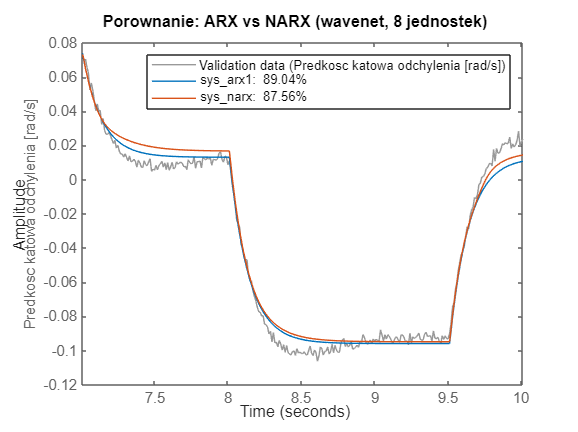

sys_narx = nlarx(data_est, [2 2 1], idWaveletNetwork(8));

figure;
compare(data_val, sys_arx1, sys_narx);
title('Porownanie: ARX vs NARX (wavenet, 8 jednostek)');

**Krok 1**. Badanie przeuczenia: zmiana liczby jednostek sieci wavenet.

units_list = [1, 2, 4, 8, 16, 32, 64, 128];
fprintf('\n%-10s  %-15s  %-15s\n', 'Jednostki', 'fit% estymacja', 'fit% walidacja')


Jednostki   fit% estymacja   fit% walidacja 



fprintf('%s\n', repmat('-', 1, 45))

---------------------------------------------



for i = 1:length(units_list)
    nu = units_list(i);
    mdl = nlarx(data_est, [2 2 1], idWaveletNetwork(nu));

    % fit% na zbiorze estymacyjnym
    y_est_pred = predict(mdl, data_est);
    fit_est = 100 * (1 - norm(data_est.y - y_est_pred.y) / ...
              norm(data_est.y - mean(data_est.y)));

    % fit% na zbiorze walidacyjnym
    y_val_pred = predict(mdl, data_val);
    fit_val = 100 * (1 - norm(data_val.y - y_val_pred.y) / ...
              norm(data_val.y - mean(data_val.y)));

    fprintf('%-10d  %-15.2f  %-15.2f\n', nu, fit_est, fit_val);
end

1           96.65            95.24          
2           96.65            95.23          
4           96.66            95.21          
8           96.67            95.21          
16          96.70            95.20          
32          96.72            95.20          
64          96.72            95.20          
128         96.72            95.20          


**Krok 2**. Inne estymatory nieliniowe.

% Zastapic idWaveletNetwork jednym z estymatorow:
%   idSigmoidNetwork lub treepartition
% Porownac wyniki z wavelet. Zapisac obserwacje.
%
% mdl_alt = nlarx(data_est, [2 2 1], ???);
% compare(data_val, sys_arx1, mdl_alt);

## Porownanie charakterystyk Bodego z transmitancja analityczna

Transmitancja analityczna: G(s) = C * (sI - A)^{-1} * B wyznaczona bezposrednio z macierzy A, B, C modelu rowerowego.

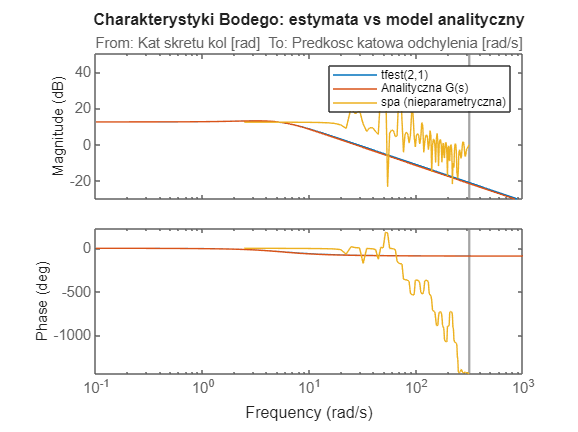

sys_analytic = tf(sys_ref);

figure;
bode(sys_tf21, sys_analytic, G_spa);
legend('tfest(2,1)', 'Analityczna G(s)', 'spa (nieparametryczna)');
title('Charakterystyki Bodego: estymata vs model analityczny');